## Advanced Part Project 1

## Miscellaneous

Adding paths and loading `.mat` files as well as importing the CIFAR10 dataset.

addpath('./functions');
addpath('./data');

load('bignet.mat')
load('ood_detection.mat')
[XTrain, YTrain, XTest, YTest] = load_data('data');

### Analyzing the network

Here I analyze the network to see which layers it is composed of.

analyzeNetwork(bignet)

### Feature Extraction

Here, I extract the features using the `activations function and set a threshold base on the feature distribution. Later, I classify the images using this threshold and compute the accuracy.`

layer = "relu_10"

layer = "relu_10"

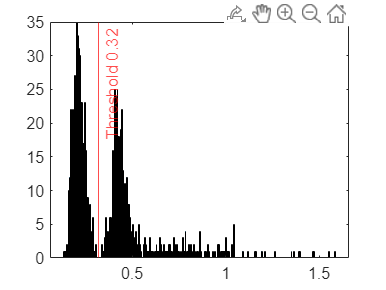

features = activations(bignet, ood_detection.data, layer, OutputAs="rows");
histogram(mean(features,2), NumBins=300)
threshold = 0.32;
xline(threshold,"r-",join(["Threshold" threshold]))

pred = mean(features,2)<threshold;
y_test = ood_detection.labels== 'ood';
tp = nnz(pred == y_test);
accuracy = tp / length(y_test);
disp(['The network achieved an accuracy of: ', num2str((accuracy)*100), '%'])

The network achieved an accuracy of: 100%


### Plotting the images

Here I plot a subset of the id and ood images and compare them side by side.

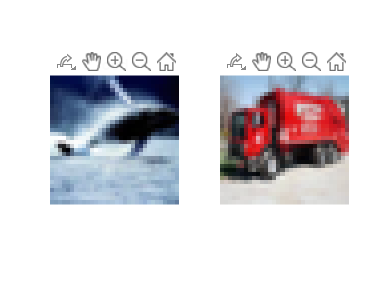

ood = find(ood_detection.labels=='ood');
id = find(ood_detection.labels=='id');
figure;
subplot(1,2,1);
imshow(ood_detection.data(:,:,:,datasample(ood,1)));
title("ood")
subplot(1,2,2);
imshow(ood_detection.data(:,:,:,datasample(id,1)));
title("id")

### Empirical Study

I try to use a differnt layer with a lower (still high) accuracy and check which images get confused as id/ood.

layer = "relu_9"

layer = "relu_9"

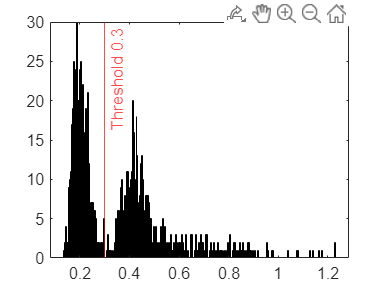

features = activations(bignet, ood_detection.data, layer, OutputAs="rows");
figure;
histogram(mean(features,2), NumBins=300)
threshold = 0.3;
xline(threshold,"r-",join(["Threshold" threshold]))

pred = mean(features,2)<threshold;
y_test = ood_detection.labels== 'ood';
tp = nnz(pred == y_test);
accuracy = tp / length(y_test);
disp(['The network achieved an accuracy of: ', num2str((accuracy)*100), '%'])

The network achieved an accuracy of: 99.3%


indeces = find(pred ~= y_test)

indeces =     84
   306
   510
   618
   707
   882
   884


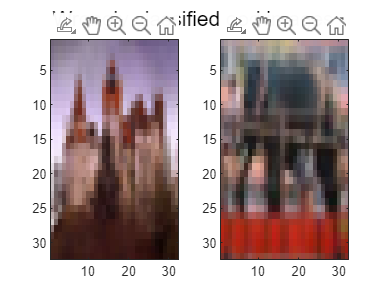

ood = find(ood_detection.labels=='ood');
id = find(ood_detection.labels=='id');
wrong_ood = intersect(ood,indeces);
wrong_id = intersect(id,indeces);
figure;
subplot(1,2,1);
idx = datasample(wrong_ood,1);
imagesc(ood_detection.data(:,:,:,idx));
idx = datasample(wrong_ood,1);
subplot(1,2,2);
imagesc(ood_detection.data(:,:,:,idx));
sgtitle("Wrongly classified ood images")